# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.9 设置特殊的图例 

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

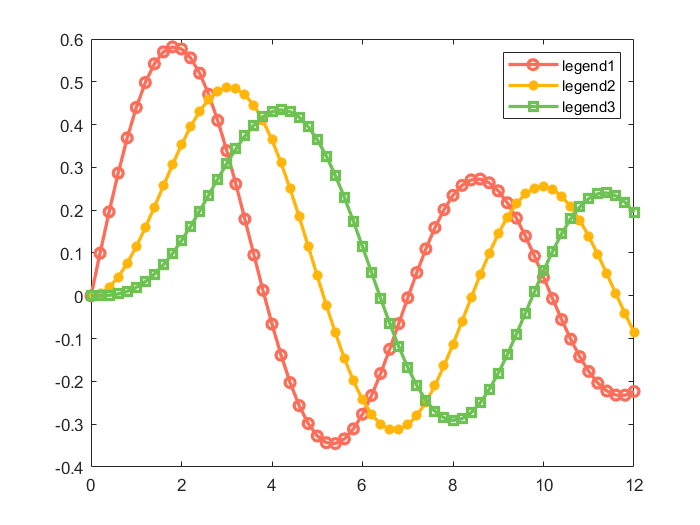

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 生成曲线数据
x = 0:0.2:12;
y1 = besselj(1, x);
y2 = besselj(2, x);
y3 = besselj(3, x);
% 先看正常绘图时的 legend，显示出来的线型、标记、颜色和曲线是对应的
figure
plot(x, y1, '-o', 'Color', all_colors(1, :), 'LineWidth', 2);
hold on
plot(x, y2, '-*', 'Color', all_colors(2, :), 'LineWidth', 2);
plot(x, y3, '-s', 'Color', all_colors(3, :), 'LineWidth', 2);
hold off
legend('legend1', 'legend2', 'legend3');

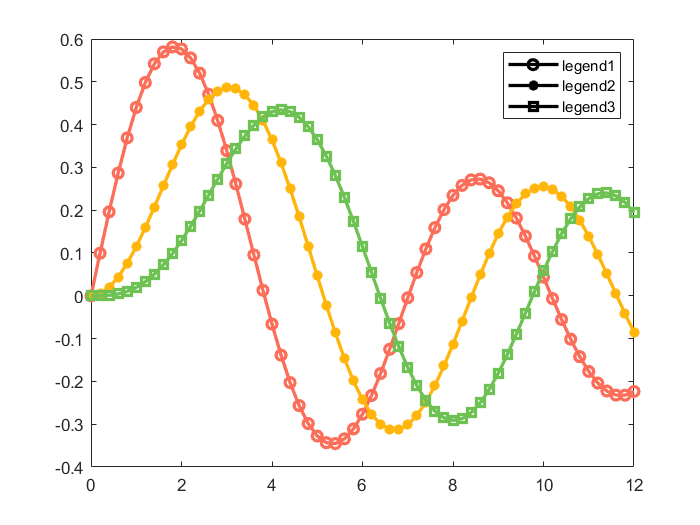

% 如果要让图例颜色都是黑色怎么实现
% 一个很笨但有效的方法，重新绘制一遍将原图覆盖
figure
plot(x, y1, '-ok', 'LineWidth', 2);
hold on 
plot(x, y2, '-*k', 'LineWidth', 2);
plot(x, y3, '-sk', 'LineWidth', 2);

plot(x, y1, '-o', 'Color', all_colors(1, :), 'LineWidth', 2);
plot(x, y2, '-*', 'Color', all_colors(2, :), 'LineWidth', 2);
plot(x, y3, '-s', 'Color', all_colors(3, :), 'LineWidth', 2);
hold off
% 只显示前面三条曲线的legend
legend('legend1', 'legend2', 'legend3');

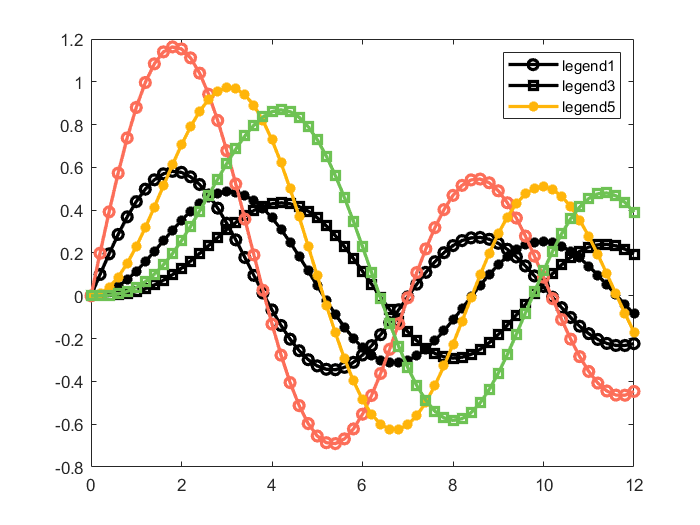

% 如果想显示指定曲线的legend
figure
h1 = plot(x, y1, '-ok', 'LineWidth', 2);
hold on 
h2 = plot(x, y2, '-*k', 'LineWidth', 2);
h3 = plot(x, y3, '-sk', 'LineWidth', 2);
h4 = plot(x, 2*y1, '-o', 'Color', all_colors(1, :), 'LineWidth', 2);
h5 = plot(x, 2*y2, '-*', 'Color', all_colors(2, :), 'LineWidth', 2);
h6 = plot(x, 2*y3, '-s', 'Color', all_colors(3, :), 'LineWidth', 2);
hold off
legend([h1, h3, h5], 'legend1', 'legend3', 'legend5');